# Particle Double Pendulum - Nonlinear and Linearized Solutions

## Problem Statement

This two-part problem is described in the Canvas assignments below. We will set up the (nonlinear) equations of motion and then solve them numerically. The results will be summarized in an x-y plot of the angular displacements. An animation will also be created to help describe the system behavior. We then linearize the EOMs and solve them (analytically - though still within Matlab) by solving the eigenvalue problem. The results of the numerical solution of the nonlinear EOMs and the analytical solution of the linearized EOMs are compared.

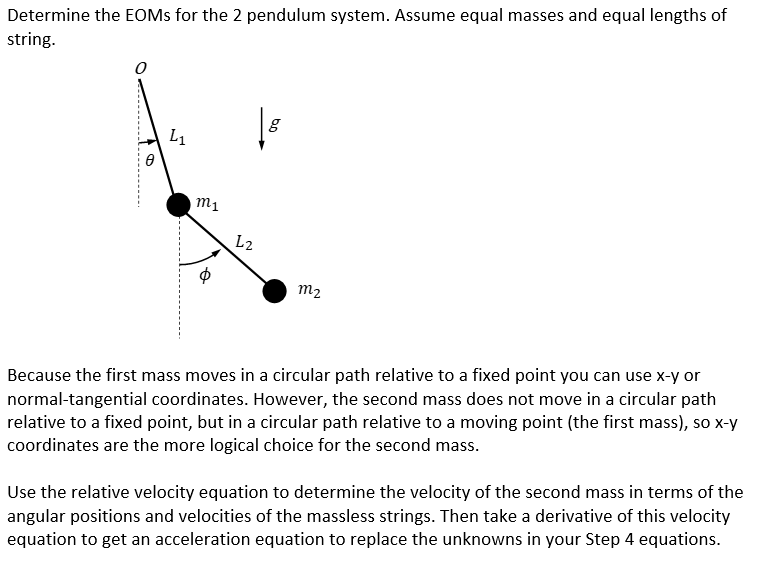

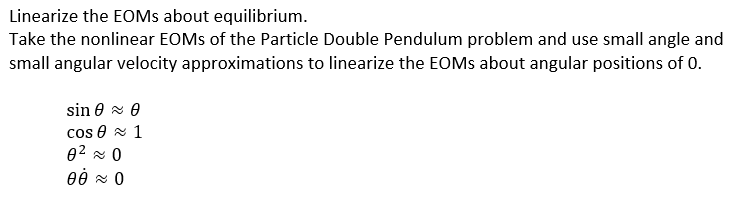

## Step 1: Conceptualize The Problem

Find the angular displacements as functions of time by determining the EOMs and numerically integrating them using ode45. The variables used for the angles will be $\theta$ and $\phi$ rather than $\theta_1$ and $\theta_2$, respectively, shown in the sketch above.

- 2 degrees of freedom

- Gravity is acting

- Masses move without any friction or drag

- Assume particle dynamics - point masses, massless rods

- Equal masses, equal lengths

- Assume initial conditions can be specified (want to study various IC's)

## Step 2: Coordinate System

A normal-tangential coordinate system is used from the origin to mass 1. A Cartesian system is used for mass 2. Constraint equations will be used to relate the Cartesian components to the angles.

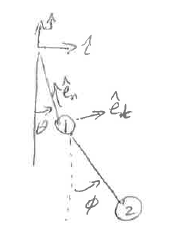

## Step 3: Free-Body Diagram

Individual FBDs for mass 1 and 2.

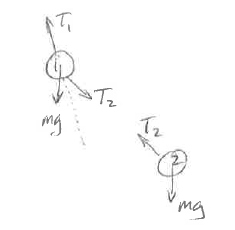

## Step 4: Fundamental Equations

The EOMs are derived starting with Newton's second law


$$\bar{F}=m\bar{a}$$


Details are in the appendix, but the resulting equations are


$$mL\dot{\theta}^2=-mg\cos{\theta}+T_1-T_2\cos{(\phi-\theta)}$$



$$mL\ddot{\theta}=-mg\sin{\theta}+T_2\sin{(\phi-\theta)}$$



$$m\ddot{x}_2=-T_2\sin{\phi}$$



$$m\ddot{y}_2=-mg+T_2\cos{\phi}$$


clear
syms m g L theta theta_dot theta_ddot phi phi_dot phi_ddot x_ddot y_ddot T1 T2

eqn(1) = m*L*theta_dot^2 == -m*g*cos(theta)+T1-T2*cos(phi-theta);
eqn(2) = m*L*theta_ddot == -m*g*sin(theta)+T2*sin(phi-theta);
eqn(3) = m*x_ddot == -T2*sin(phi);
eqn(4) = m*y_ddot == -m*g+T2*cos(phi);

## Step 5: Knowns and Unknowns

### Knowns


$$m, g, L, \theta_0, \dot{\theta}_0, \phi_0, \dot{\phi}_0$$


### Unknowns

$\theta$: angular position of mass 1 (measured from downward vertical)

$\phi$: angular position of mass 2 (measured from downward vertical)

$T_1$: force in pendulum rod 1

$T_2$: force in pendulum rod 2

$x$: horizontal displacement of mass 2

$y$: vertical displacement of mass 2

## Step 6: Constraints

Constraints between acceleration components.


$$\ddot{x}_2=L\ddot{\theta}\cos{\theta}-L\dot{\theta}^2\sin{\theta}+L\ddot{\phi}\cos{\phi}-L\dot{\phi}^2\sin{\phi}$$



$$\ddot{y}_2=L\ddot{\theta}\sin{\theta}+L\dot{\theta}^2\cos{\theta}+L\ddot{\phi}\sin{\phi}+L\dot{\phi}^2\cos{\phi}$$


eqn(5:6) = [x_ddot,y_ddot] == L*theta_ddot*[cos(theta),sin(theta)]+...
    L*theta_dot^2*[-sin(theta),cos(theta)]+L*phi_ddot*[cos(phi),sin(phi)]+...
    L*phi_dot^2*[-sin(phi),cos(phi)];

Now have 6 eqs and 6 unknowns.

## Step 7: Obtain the EOMs

### Nonlinear EOMs

unknowns = solve(eqn,[theta_ddot,phi_ddot,T1,T2,x_ddot,y_ddot]);
theta_ddot = simplify(unknowns.theta_ddot)

$$theta\_ddot = -\frac{2\,L\,\sin\left(\varphi -\theta \right)\,{\dot{\varphi }}^{2}+L\,\sin\left(2\,\varphi -2\,\theta \right)\,{\dot{\theta }}^{2}+g\,\sin\left(2\,\varphi -\theta \right)-3\,g\,\sin\left(\theta \right)}{L\,\left(\cos\left(2\,\varphi -2\,\theta \right)-3\right)}$$

phi_ddot = simplify(unknowns.phi_ddot)

$$phi\_ddot = \frac{L\,\sin\left(2\,\varphi -2\,\theta \right)\,{\dot{\varphi }}^{2}+4\,L\,\sin\left(\varphi -\theta \right)\,{\dot{\theta }}^{2}+2\,g\,\sin\left(\varphi \right)+2\,g\,\sin\left(\varphi -2\,\theta \right)}{L\,\left(\cos\left(2\,\varphi -2\,\theta \right)-3\right)}$$

### Linearized EOMs

Now want to linearize these equations so that we can solve analytically. Use small angle approximation: $\sin(x) \approx x \enspace, \enspace \cos(x) \approx 1$, and use small angular velocity approximation: $\dot{\theta}^2,\dot{\phi}^2 \approx 0$. 

Start by using "expand" to replace sum/difference of angles using trig identities.

LinEOMs = expand([unknowns.theta_ddot;unknowns.phi_ddot])

Now apply the linearization approximations for angles and angular velocities

LinEOMs = subs(LinEOMs,[str2sym('sin(theta)'),str2sym('cos(theta)'),...
    str2sym('sin(phi)'),str2sym('cos(phi)'),str2sym('theta_dot^2'),str2sym('phi_dot^2')],...
    [theta,1,phi,1,0,0])

$$LinEOMs = \begin{array}{l} \left(\begin{array}{c} \frac{g\,\varphi }{\sigma_{1}}-\frac{2\,g\,\theta }{\sigma_{1}}-\frac{g\,\varphi^{2}\,\theta }{\sigma_{1}}\\ \frac{2\,g\,\theta }{\sigma_{1}}-\frac{2\,g\,\varphi }{\sigma_{1}}+\frac{g\,\varphi \,\theta^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,L\,\varphi^{2}-2\,L\,\varphi \,\theta +L\,\theta^{2}+L \end{array}$$

The resulting equations show there are now products of angles remaining. Any products of angles will be much smaller than a linear term, so we eliminate those terms.

LinEOMs = subs(LinEOMs,[theta*phi,theta^2,phi^2],[0,0,0])

$$LinEOMs = \left(\begin{array}{c} \frac{g\,\varphi }{L}-\frac{2\,g\,\theta }{L}\\ \frac{2\,g\,\theta }{L}-\frac{2\,g\,\varphi }{L} \end{array}\right)$$

Linearization is now complete. Re-write these equations in the matrix form: $\ddot{\bar{x}} = [A]\bar{x}$

Factor out the vector $\left[ \matrix{\theta \cr \phi}\right]$

A = equationsToMatrix(LinEOMs,[theta;phi])

$$A = \left(\begin{array}{cc} -\frac{2\,g}{L} & \frac{g}{L}\\ \frac{2\,g}{L} & -\frac{2\,g}{L} \end{array}\right)$$

so our two linear ODEs are


$$\left[\begin{array}{cc} \ddot{\theta} \\ \ddot{\phi} \end{array}\right] = \frac{g}{L}\left[\begin{array}{cc} -2 & 1\\ 2 & -2 \end{array}\right] \left[\begin{array}{cc} \theta \\ \phi \end{array}\right] $$


## Step 8: Solve the EOMs

### Solve nonlinear EOMs

Make all state variables symbolic functions of time

syms theta(t) theta_dot(t) phi(t) phi_dot(t)

Substitute these symbolic functions into the EOMs. Then have Matlab produce the eom sub-function using the odeFunction command. The 3 sets of arguments passed to odeFunction are the expressions for the derivatives of the state variables, the state variables, and then any other parameters that appear in the derivative expressions. Note that the order of the state variables and their derivatives is arbitrary but must be consistent.

accelEOMs = subs([theta_ddot;phi_ddot],...
    [str2sym('theta'),str2sym('phi'),str2sym('theta_dot'),str2sym('phi_dot')],...
    [theta,phi,theta_dot,phi_dot]);
eom = odeFunction([theta_dot;phi_dot;accelEOMs],[theta;phi;theta_dot;phi_dot],g,L);

Specify parameter values and integrate EOMs. Order of IC's must match state variables in odeFunction call.

gn = 9.81; % gravitational constant, m/s^2
Ln = 0.33; % length of each rod, m
IC(1) = pi/36; % initial theta
IC(2) = pi/18; % inital phi
IC(3) = 0; % initial theta-dot
IC(4) = 0; % initial phi-dot
t0 = 0; % initial time
tf = 10; % final time
ntime = 301; % number of time points
[T,S] = ode45(@(t,s)eom(t,s,gn,Ln),linspace(t0,tf,ntime),IC);

Plot animation of motion:

%ax1 = Ln*sin(S(:,1));
%ay1 = -Ln*cos(S(:,1));
%ax2 = Ln*(sin(S(:,1))+sin(S(:,2)));
%ay2 = -Ln*(cos(S(:,1))+cos(S(:,2)));
%figure("Visible","on")
%h = plot([0,ax1(1)],[0,ay1(1)],'-k',[ax1(1),ax2(1)],[ay1(1),ay2(1)],...
%    '-ko','LineWidth',1,'MarkerSize',10,'MarkerFaceColor','k');
%xlabel('x, m')
%ylabel('y, m')
%axis equal
%ylim([-2*Ln*1.1,0])
%xlim([-2*Ln,2*Ln])
%for i = 2:2
%    set(h(1),'XData',[0,ax1(i)],'YData',[0,ay1(i)]);
%    set(h(2),'XData',[ax1(i),ax2(i)],'YData',[ay1(i),ay2(i)]);
%    drawnow
%end

Plot time history of angles

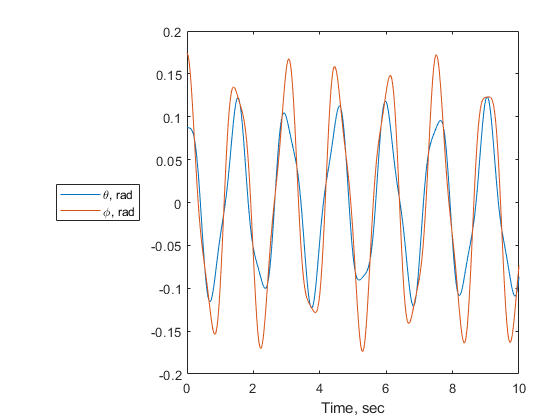

plot(T,S(:,1:2),'-')
xlabel('Time, sec')
legend('\theta, rad','\phi, rad','Location','WestOutside')

### Solve Linearized EOMs

Obtain "analytical" solution by solving the linear differential equations. We do this by solving an eigenvector/eigenvalue problem. Repeating from above, our linear ODEs are


$$\left[\begin{array}{cc} \ddot{\theta} \\ \ddot{\phi} \end{array}\right] = \frac{g}{L}\left[\begin{array}{cc} -2 & 1\\ 2 & -2 \end{array}\right] \left[\begin{array}{cc} \theta \\ \phi \end{array}\right] $$


So $x(1)$ is the linearized approximation for $\theta$ and $x(2)$ is the linearized approximation for $\phi$.

Turn A into a number, double precision:

An = eval(subs(A,[g,L],[gn,Ln]));

Solve Eigenvalue/Eigenvector problem using "eig" function. The eigenvectors are returned as columns of a matrix [c] and the eigenvalues are returned as a diagonal matrix. The columns of these two matrices "go together" - the first column of [c] is the first eigenvector, and the first column of rsquared is the corresponding eigenvalue, etc.

[c,rsquared] = eig(An)

c =     0.5774   -0.5774
    0.8165    0.8165


rsquared =   -17.4138         0
         0 -101.4953


Both $r^2$ are negative so r is pure imaginary thus:

 
$$\bar{x} = \bar{c}_1e^{\pm i\omega_1 t}+\bar{c}_2e^{\pm i\omega_2 t} \\ \enspace
= \bar{c}_1\left(A\cos(\omega_1t)+B\sin(\omega_1t)\right)+
\bar{c}_2\left(C\cos(\omega_2t)+D\sin(\omega_2t)\right)$$


The natural frequencies are:

omega = imag(sqrt([rsquared(1,1);rsquared(2,2)]))

omega =     4.1730
   10.0745


To solve for the coefficients use the initial conditions.


$$\bar{x}(0) = \bar{c}_1A+\bar{c}_2C = [\bar{c}_1 \ \bar{c}_2]
\left[\matrix{A \cr C} \right] = [c]\left[\matrix{A \cr C} \right]$$


thus:


$$\left[\matrix{A \cr C} \right] = [c]^{-1}\bar{x}(0)$$


ACcoef = c^-1*IC(1:2)';

Note the transpose in the equation above. The velocity is obtained by taking the derivative, $\dot{\bar{x}} = \omega_1\bar{c}_1\left(-A\sin(\omega_1t)+B\cos(\omega_1t)\right)+
\omega_2\bar{c}_2\left(-C\sin(\omega_2t)+D\cos(\omega_2t)\right)$. 

So we can find the B and D coefficients,


$$\dot{\bar{x}}(0) = \omega_1\bar{c}_1B+
\omega_2\bar{c}_2D = [c]\left[\matrix{\omega_1B \cr \omega_2D} \right]$$


BDcoef = c^-1*IC(3:4)'./omega;

We now have all of the coefficients so we can find $x(t)$ for any time. Note that in Matlab code we have to use element-by-element multiplication (the ".") and be careful with vector dimensions (use the transpose of T vector, for example).

x = c(:,1).*(ACcoef(1)*cos(omega(1)*T')+BDcoef(1)*sin(omega(1)*T'))+...
    c(:,2).*(ACcoef(2)*cos(omega(2)*T')+BDcoef(2)*sin(omega(2)*T')); % 2 rows by n columns

And then we can overlay the previous plot of the nonlinear solution with our linearized solution (remember that $x(1)$ is the linearized approximation for $\theta$ and $x(2)$ is the linearized approximation for $\phi$).

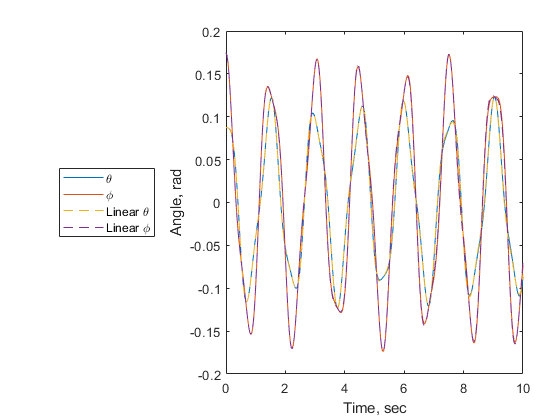

figure
plot(T,S(:,1:2),'-',T',x,'--')
xlabel('Time, sec')
ylabel('Angle, rad')
legend('\theta','\phi','Linear \theta','Linear \phi','Location','WestOutside')

In this case we have great agreement between the two solutions. The more valid the small angular position and velocity approximations are, the better correlation between the nonlinear and linear solutions.

#### Solve for Initial Conditions that produce the 2 modes of vibration:

A mode of vibration is when only 1 of the *n* natural frequencies is being excited. In this problem that would mean that for the first mode of vibration the coefficients C and D must be zero. 


$$\bar{x}(0) = [c]\left[\matrix{A \cr C} \right] = [c]\left[\matrix{A \cr 0} \right] \\
A = \theta(0)/c_{11}$$


Acoef = IC(1)/c(1,1);


$$\dot{\bar{x}}(0) = [c]\left[\matrix{\omega_1B \cr \omega_2D} \right] = [c]\left[\matrix{\omega_1B \cr 0} \right] \\
B = \dot{\theta}(0)/\left(c_{11}\omega_1\right)$$


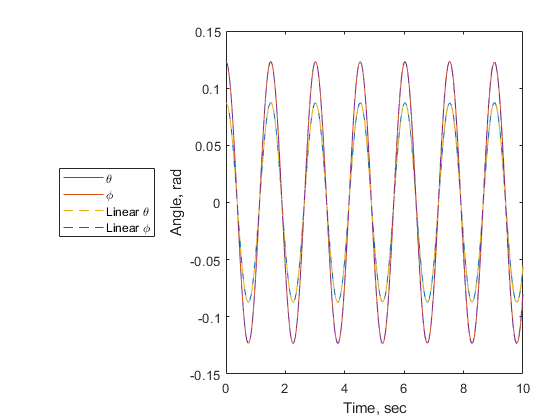

Bcoef = IC(3)/(c(1,1)*omega(1));
x1 = c(:,1).*(Acoef*cos(omega(1)*T')+Bcoef*sin(omega(1)*T'));
[T,S1] = ode45(@(t,s)eom(t,s,gn,Ln),T,[x1(:,1);IC(3:4)']);
figure
title('Mode 1')
plot(T,S1(:,1:2),'-',T',x1,'--')
xlabel('Time, sec')
ylabel('Angle, rad')
legend('\theta','\phi','Linear \theta','Linear \phi','Location','WestOutside')

There is physical significance to the mode shapes. For mode 1, note that $\theta$ and $\phi$ are in phase - so the first mode shape is both pendulums swinging back and forth together. Notice that the period of oscialltion is about 1.5 sec (can calculate exact value from $\omega_1$).

Repeat for second mode of vibration, the coefficients A and B must be zero.


$$\bar{x}(0) = [c]\left[\matrix{A \cr C} \right] = [c]\left[\matrix{0 \cr C} \right] \\
C = \theta(0)/c_{12}$$


Ccoef = IC(1)/c(1,2);


$$\dot{\bar{x}}(0) = [c]\left[\matrix{\omega_1B \cr \omega_2D} \right] = [c]\left[\matrix{0 \cr \omega_2D} \right] \\
D = \dot{\theta}(0)/\left(c_{12}\omega_2\right)$$


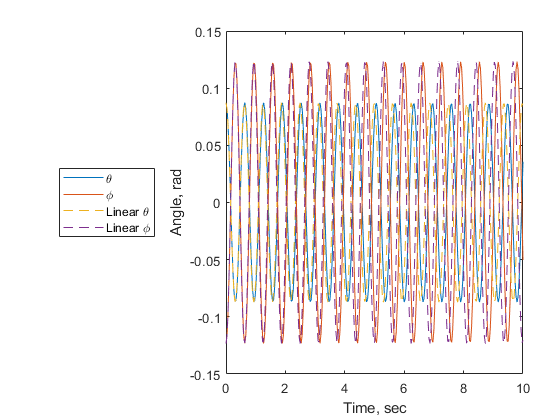

Dcoef = IC(3)/(c(1,2)*omega(2));
x2 = c(:,2).*(Ccoef*cos(omega(2)*T')+Dcoef*sin(omega(2)*T'));
[T,S2] = ode45(@(t,s)eom(t,s,gn,Ln),T,[x2(:,1);IC(3:4)']);
figure
title('Mode 2')
plot(T,S2(:,1:2),'-',T',x2,'--')
xlabel('Time, sec')
ylabel('Angle, rad')
legend('\theta','\phi','Linear \theta','Linear \phi','Location','WestOutside')

The second mode does not correlate as well with the true nonlinear EOM solution since the small angular velocity approximation is not as valid; much faster oscillations than mode 1.

Also note that $\theta$ and $\phi$ are out of phase - so the physical meaning of the second mode shape is each pendulum swinging back and forth but in opposite directions. And the corresponding frequency of that motion is much higher.

## Step 9: Does It Make Sense?

### Units:

Check Equations

u = symunit;
Variables.m = m*u.kg;
Variables.T1 = T1*u.N;
Variables.T2 = T2*u.N;
Variables.g = g*u.m/u.s^2;
Variables.L = L*u.m;
Variables.x_ddot = x_ddot*u.m/u.s^2;
Variables.y_ddot = y_ddot*u.m/u.s^2;
Variables.theta_dot = theta_dot/u.s;
Variables.phi_dot = phi_dot/u.s;
Variables.theta_ddot = theta_ddot/u.s^2;
Variables.phi_ddot = phi_ddot/u.s^2;
eqnUnits = subs(eqn,Variables);
checkUnits(eqnUnits)

ans = struct with fields:
    Consistent: [1 1 1 1 1 1]
    Compatible: [1 1 1 1 1 1]


All equations have consistent and compatible units

Check EOMs

theta_ddotEOMUnits = subs(theta_ddot,Variables);
[~,thetaEOMUnits] = separateUnits(theta_ddotEOMUnits);
thetaEOMUnits

$$thetaEOMUnits = \frac{1}{s^{2}}$$

Confirms that $\ddot{\theta}$ is in $\text{rad/s}^2$

phi_ddotEOMUnits = subs(phi_ddot,Variables);
[~,phiEOMUnits] = separateUnits(phi_ddotEOMUnits);
phiEOMUnits

$$phiEOMUnits = \frac{1}{s^{2}}$$

Confirms that $\ddot{\phi}$ is in $\text{rad/s}^2$

### Magnitudes and Signs

In this work, the magnitude and signs are confirmed with the animation showing that the output looks physically reasonable. The magnitude of the oscillations are not growing or decaying, consistent with our assumptions of no losses. The signs can be further tested and confirmed by trying different initial conditions with both positive and negative initial angles.

## Appendix

### Contributions

who did what...

### Attachments

EOMs derived during class lecture.